clear all
close all
clc

%Parametros montagem
Z_tela = 1270 %mm

Z_tela = 1270

Z_kuka = -150 %mm

Z_kuka = -150

alpha = -pi/2

alpha = -1.5708

hom_matrix = [1 0 0 250;0 cos(alpha) -sin(alpha) 150;0 sin(alpha) cos(alpha) 80;0 0 0 1]

hom_matrix =     1.0000         0         0  250.0000
         0    0.0000    1.0000  150.0000
         0   -1.0000    0.0000   80.0000
         0         0         0    1.0000



%parametros camera
f = 3.67 %mm

f = 3.6700

n_w = 1920 %px

n_w = 1920

n_h = 1080 %px

n_h = 1080

NP = n_w*n_h %px x px

NP = 2073600


sensor_size = 1/2.88*25.4 %mm

sensor_size = 8.8194


p_h = sqrt(sensor_size^2/(16^2/9^2+1))

p_h = 4.3238

p_w = p_h*16/9

p_w = 7.6868


ro_w = p_w/n_w %mm/px

ro_w = 0.0040

ro_h = p_h/n_h %mm/px

ro_h = 0.0040


%posicao em pixel
u = 300

u = 300

v = 300

v = 300


%resolucao imagem
res_w = 640

res_w = 640

res_h = 480

res_h = 480


x = ro_w*(u-res_w/2)

x = -0.0801

y = ro_h*(v-res_h/2)

y = 0.2402


%posicao na tela
X_tela = x*Z_tela/f

X_tela = -27.7085

Y_tela = y*Z_tela/f

Y_tela = 83.1254


%posicao kuka
X_kuka = X_tela

X_kuka = -27.7085

Y_kuka = Y_tela

Y_kuka = 83.1254



%Transformando os sistemas de coordenadas:
pos_b = [-250 80 -150]

pos_b =   -250    80  -150


pos_b_tela = mtimes(hom_matrix,[X_tela;Y_tela;Z_tela;1])

pos_b_tela = 1.0e+03 *

    0.2223
    1.4200
   -0.0031
    0.0010


pos_b_tela_t = pos_b_tela'

pos_b_tela_t = 1.0e+03 *

    0.2223    1.4200   -0.0031    0.0010



%plotando

x_max_tela = ro_w*n_w/2*Z_tela/f

x_max_tela = 1.3300e+03

y_max_tela = ro_w*n_h/2*Z_tela/f

y_max_tela = 748.1289


x_plot = -x_max_tela:1:x_max_tela

x_plot = 1.0e+03 *

   -1.3300   -1.3290   -1.3280   -1.3270   -1.3260   -1.3250   -1.3240   -1.3230   -1.3220   -1.3210   -1.3200   -1.3190   -1.3180   -1.3170   -1.3160   -1.3150   -1.3140   -1.3130   -1.3120   -1.3110   -1.3100   -1.3090   -1.3080   -1.3070   -1.3060   -1.3050   -1.3040   -1.3030   -1.3020   -1.3010   -1.3000   -1.2990   -1.2980   -1.2970   -1.2960   -1.2950   -1.2940   -1.2930   -1.2920   -1.2910   -1.2900   -1.2890   -1.2880   -1.2870   -1.2860   -1.2850   -1.2840   -1.2830   -1.2820   -1.2810


y_plot = -y_max_tela:1:y_max_tela

y_plot =  -748.1289 -747.1289 -746.1289 -745.1289 -744.1289 -743.1289 -742.1289 -741.1289 -740.1289 -739.1289 -738.1289 -737.1289 -736.1289 -735.1289 -734.1289 -733.1289 -732.1289 -731.1289 -730.1289 -729.1289 -728.1289 -727.1289 -726.1289 -725.1289 -724.1289 -723.1289 -722.1289 -721.1289 -720.1289 -719.1289 -718.1289 -717.1289 -716.1289 -715.1289 -714.1289 -713.1289 -712.1289 -711.1289 -710.1289 -709.1289 -708.1289 -707.1289 -706.1289 -705.1289 -704.1289 -703.1289 -702.1289 -701.1289 -700.1289 -699.1289



[X_plot,Y_plot] = meshgrid(x_plot,y_plot)

X_plot = 1.0e+03 *

   -1.3300   -1.3290   -1.3280   -1.3270   -1.3260   -1.3250   -1.3240   -1.3230   -1.3220   -1.3210   -1.3200   -1.3190   -1.3180   -1.3170   -1.3160   -1.3150   -1.3140   -1.3130   -1.3120   -1.3110   -1.3100   -1.3090   -1.3080   -1.3070   -1.3060   -1.3050   -1.3040   -1.3030   -1.3020   -1.3010   -1.3000   -1.2990   -1.2980   -1.2970   -1.2960   -1.2950   -1.2940   -1.2930   -1.2920   -1.2910   -1.2900   -1.2890   -1.2880   -1.2870   -1.2860   -1.2850   -1.2840   -1.2830   -1.2820   -1.2810
   -1.3300   -1.3290   -1.3280   -1.3270   -1.3260   -1.3250   -1.3240   -1.3230   -1.3220   -1.3210   -1.3200   -1.3190   -1.3180   -1.3170   -1.3160   -1.3150   -1.3140   -1.3130   -1.3120   -1.3110   -1.3100   -1.3090   -1.3080   -1.3070   -1.3060   -1.3050   -1.3040   -1.3030   -1.3020   -1.3010   -1.3000   -1.2990   -1.2980   -1.2970   -1.2960   -1.2950   -1.2940   -1.2930   -1.2920   -1.2910   -1.2900   -1.2890   -1.2880   -1.2870   -1.2860   -1.2850   -1.2840   -1.283

Y_plot =  -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289 -748.1289
 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289 -747.1289


Z_plot = zeros(size(X_plot,1),size(X_plot,2))

Z_plot =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

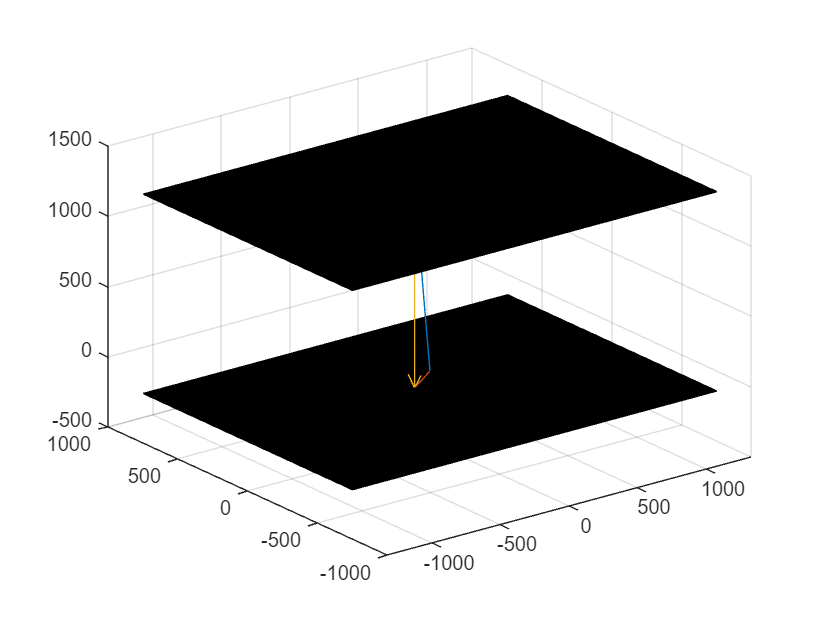


surf(-1.5:0.1:1.5,-1.5:0.1:1.5,zeros(31,31))
hold on
surf(X_plot,Y_plot,Z_plot+Z_tela)
surf(X_plot,Y_plot,Z_plot+Z_kuka)

quiver3(x,y,0,X_tela-x,Y_tela-y,Z_tela-0,0)
quiver3(x,y,0,X_kuka-x,Y_kuka-y,Z_kuka-0,0)
quiver3(X_tela,Y_tela,Z_tela,0,0,Z_kuka-Z_tela,0)


%%quiver(pos_b(1),pos_b(2),pos_b(3),pos_b_tela_t(1)-pos_b(1),pos_b_tela_t(2)-pos_b(2),pos_b_tela_t(3)-pos_b(3),0)

Error using quiver
QUIVER does not support 7 leading numeric input(s).